# Build graphs & calculate graph similarity

clc
clearvars
close all

nlist = readtable("./sim_data/assembly_line_4players8_nlist.csv");
elist = readtable("./sim_data/assembly_line_4players8_elist.csv");

nlist.Properties.VariableNames = {'Name','Label'};
nlist.Name = string(nlist.Name);
num_nodes = size(nlist,1);
num_edges = size(elist,1);
num_players = (size(elist,2)-1)/2;

% initialize graphs
G = cell(4,1);
A = cell(4,1);
for i=1:num_players
    G{i} = digraph(zeros(num_nodes,num_nodes),nlist);
    A{i} = adjacency(G{i});
end

out_mx = NaN(num_edges,nchoosek(num_players,2),2); % num_edges x 4C2 x 2 (adj_spectl,feat_sim)
for i=1:num_edges
    r = table2array(elist(i,:));
    gfeat = NaN(num_players,num_nodes,7);

    for j=1:num_players
        s = r(2*j);
        t = r(2*j+1);

        if (s==0)&&(t==0)
            % no update 
        elseif xor(s==0,t==0)
            error("Invalid edge")
        else
            [edge_exist,update_idx] = ismember([s,t],str2double(G{j}.Edges.EndNodes),'rows');
            if (all(edge_exist))
                w = G{j}.Edges.Weight;
                G{j}.Edges.Weight(update_idx) = w(update_idx)+1;
            else
                G{j} = addedge(G{j},num2str(s),num2str(t),1);
            end
        end
        % adjacency matrices for spectral distance
        A{j} = adjacency(G{j});

        % graph features for feature-based distance        
        gfeat(j,:,1) = centrality(G{j},'outdegree','Importance',G{j}.Edges.Weight);
        gfeat(j,:,2) = centrality(G{j},'indegree','Importance',G{j}.Edges.Weight);
        gfeat(j,:,3) = centrality(G{j},'outcloseness');
        gfeat(j,:,4) = centrality(G{j},'incloseness');
        gfeat(j,:,5) = centrality(G{j},'betweenness');
        gfeat(j,:,6) = centrality(G{j},'pagerank','Importance',G{j}.Edges.Weight);
        gfeat(j,:,7) = centrality(G{j},'hubs','Importance',G{j}.Edges.Weight);
    end
    
    % graph feature & similarity
    l = 0;
    for j=1:(num_players-1)
        lambdaj = eigs(A{j});
        n = 1+l;
        for k=(j+1):(num_players)
            lambdak = eigs(A{k});
            out_mx(i,n,1) = norm(lambdaj-lambdak,2); % spectral
            out_mx(i,n,2) = norm(gfeat(j,:,:)-gfeat(k,:,:),'fro'); % feature based
            n = n+1;
        end
        l = l+(num_players-j);
    end
end

# Visualize the results

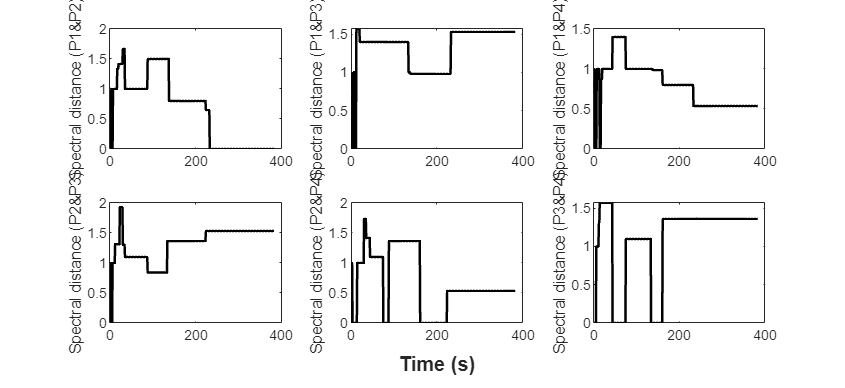

figure('Color','w','Position',[0,0,1200,550])
tle = tiledlayout(2,3);
xlabel(tle,"Time (s)", 'FontWeight','bold')

nexttile
plot(out_mx(:,1,1),'LineWidth',1.5,'Color','black')
ylabel("Spectral distance (P1&P2)")

nexttile
plot(out_mx(:,2,1),'LineWidth',1.5,'Color','black')
ylabel("Spectral distance (P1&P3)")

nexttile
plot(out_mx(:,3,1),'LineWidth',1.5,'Color','black')
ylabel("Spectral distance (P1&P4)")

nexttile
plot(out_mx(:,4,1),'LineWidth',1.5,'Color','black')
ylabel("Spectral distance (P2&P3)")

nexttile
plot(out_mx(:,5,1),'LineWidth',1.5,'Color','black')
ylabel("Spectral distance (P2&P4)")

nexttile
plot(out_mx(:,6,1),'LineWidth',1.5,'Color','black')
ylabel("Spectral distance (P3&P4)")

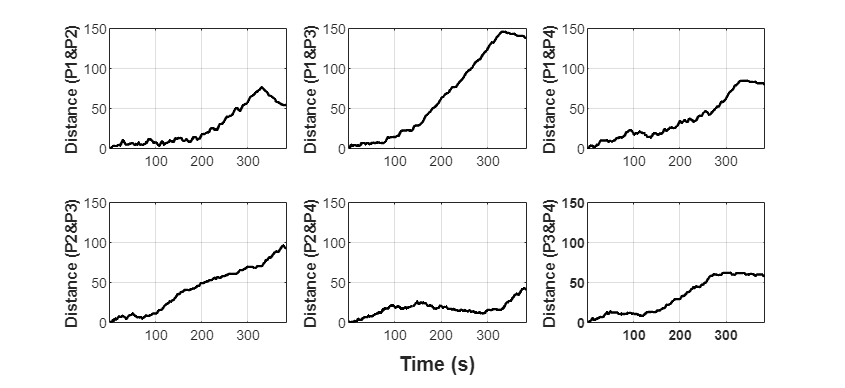

figure('Color','w','Position',[0,0,1200,550])
tle = tiledlayout(2,3);
xlabel(tle,"Time (s)", 'FontWeight','bold')

nexttile
plot(out_mx(:,1,2),'LineWidth',1.5,'Color','black')
xlim('tight')
ylim([0,150])
ylabel("Distance (P1&P2)",'FontWeight','bold')
grid on

nexttile
plot(out_mx(:,2,2),'LineWidth',1.5,'Color','black')
xlim('tight')
ylim([0,150])
ylabel("Distance (P1&P3)",'FontWeight','bold')
grid on

nexttile
plot(out_mx(:,3,2),'LineWidth',1.5,'Color','black')
xlim('tight')
ylim([0,150])
ylabel("Distance (P1&P4)",'FontWeight','bold')
grid on

nexttile
plot(out_mx(:,4,2),'LineWidth',1.5,'Color','black')
xlim('tight')
ylim([0,150])
ylabel("Distance (P2&P3)",'FontWeight','bold')
grid on

nexttile
plot(out_mx(:,5,2),'LineWidth',1.5,'Color','black')
xlim('tight')
ylim([0,150])
ylabel("Distance (P2&P4)",'FontWeight','bold')
grid on

nexttile
plot(out_mx(:,6,2),'LineWidth',1.5,'Color','black')
xlim('tight')
ylim([0,150])
ylabel("Distance (P3&P4)",'FontWeight','bold')
grid on
set(gca,'FontWeight','bold')

# Repeat the same procedure for craft data

clc
clearvars
close all

nlist = readtable("./sim_data/craft_4players8_nlist.csv");
elist = readtable("./sim_data/craft_4players8_elist.csv");

nlist.Properties.VariableNames = {'Name','Label'};
nlist.Name = string(nlist.Name);
num_nodes = size(nlist,1);
num_edges = size(elist,1);

edge_wcutoff = 16;
num_players = (size(elist,2)-1)/2;

% initialize graphs
G = cell(4,1);
A = cell(4,1);
for i=1:num_players
    G{i} = digraph(zeros(num_nodes,num_nodes),nlist);
    A{i} = adjacency(G{i});
end

out_mx = NaN(num_edges,nchoosek(num_players,2),2); % num_edges x 4C2 x 2 (adj_spectl,feat_sim)
for i=1:num_edges
    r = table2array(elist(i,:));
    gfeat = NaN(num_players,num_nodes,7);

    for j=1:num_players
        s = r(2*j);
        t = r(2*j+1);

        if (s==0)&&(t==0)
            % no update 
        elseif xor(s==0,t==0)
            error("Invalid edge")
        else
            [edge_exist,update_idx] = ismember([s,t],str2double(G{j}.Edges.EndNodes),'rows');
            if (all(edge_exist))
                w = G{j}.Edges.Weight;
                if (w(update_idx) >= edge_wcutoff)
                    G{j}.Edges.Weight(update_idx) = w(update_idx)+(0.5)^(w(update_idx)-edge_wcutoff+1);
                else
                    G{j}.Edges.Weight(update_idx) = w(update_idx)+1;
                end
            else
                G{j} = addedge(G{j},num2str(s),num2str(t),1);
            end
        end
        % adjacency matrices for spectral distance
        A{j} = adjacency(G{j});

        % graph features for feature-based distance        
        gfeat(j,:,1) = centrality(G{j},'outdegree','Importance',G{j}.Edges.Weight);
        gfeat(j,:,2) = centrality(G{j},'indegree','Importance',G{j}.Edges.Weight);
        gfeat(j,:,3) = centrality(G{j},'outcloseness');
        gfeat(j,:,4) = centrality(G{j},'incloseness');
        gfeat(j,:,5) = centrality(G{j},'betweenness');
        gfeat(j,:,6) = centrality(G{j},'pagerank','Importance',G{j}.Edges.Weight);
        gfeat(j,:,7) = centrality(G{j},'hubs','Importance',G{j}.Edges.Weight);
    end
    
    % graph feature & similarity
    l = 0;
    for j=1:(num_players-1)
        lambdaj = eigs(A{j});
        n = 1+l;
        for k=(j+1):(num_players)
            lambdak = eigs(A{k});
            out_mx(i,n,1) = norm(lambdaj-lambdak,2); % spectral
            out_mx(i,n,2) = norm(gfeat(j,:,:)-gfeat(k,:,:),'fro'); % feature based
            n = n+1;
        end
        l = l+(num_players-j);
    end
end

figure('Color','w','Position',[0,0,1200,550])
tle = tiledlayout(2,3);
xlabel(tle,"Time (s)", 'FontWeight','bold')

nexttile
plot(out_mx(:,1,2),'LineWidth',1.5,'Color','black')
ylim([0,60])
ylabel("Distance (P1&P2)",'FontWeight','bold')

nexttile
plot(out_mx(:,2,2),'LineWidth',1.5,'Color','black')
ylim([0,60])
ylabel("Distance (P1&P3)",'FontWeight','bold')

nexttile
plot(out_mx(:,3,2),'LineWidth',1.5,'Color','black')
ylim([0,60])
ylabel("Distance (P1&P4)",'FontWeight','bold')

nexttile
plot(out_mx(:,4,2),'LineWidth',1.5,'Color','black')
ylim([0,60])
ylabel("Distance (P2&P3)",'FontWeight','bold')

nexttile
plot(out_mx(:,5,2),'LineWidth',1.5,'Color','black')
ylim([0,60])
ylabel("Distance (P2&P4)",'FontWeight','bold')

nexttile
plot(out_mx(:,6,2),'LineWidth',1.5,'Color','black')
ylim([0,60])
ylabel("Distance (P3&P4)",'FontWeight','bold')

# Build graphs for visualization

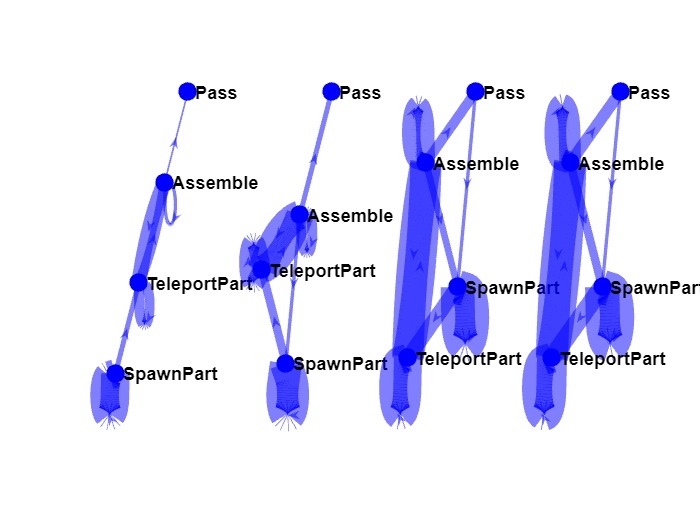

clc
clearvars
close all

nlist = readtable("./sim_data/assembly_line_4players8_nlist.csv");
elist = readtable("./sim_data/assembly_line_4players8_elist.csv");

nlist.Properties.VariableNames = {'Name','Label'};
nlist.Name = string(nlist.Name);
num_nodes = size(nlist,1);
num_edges = size(elist,1);

edge_wcutoff = 16;
num_players = (size(elist,2)-1)/2;

% initialize graphs; snap graphs at 4 time points
G = cell(4,1);
Gsnaps = cell(4,4);
for i=1:num_players
    G{i} = digraph(zeros(num_nodes,num_nodes),nlist);
end
snap_pts = [floor(quantile(1:num_edges,0.25)),floor(quantile(1:num_edges,0.5)),...
    floor(quantile(1:num_edges,0.75)),floor(quantile(1:num_edges,1))];

% have graphs evolve
tpointer = 1;
for i=1:num_edges
    r = table2array(elist(i,:));
    for j=1:num_players
        s = r(2*j);
        t = r(2*j+1);

        if (s==0)&&(t==0)
            % no update 
        elseif xor(s==0,t==0)
            error("Invalid edge")
        else
            [edge_exist,update_idx] = ismember([s,t],str2double(G{j}.Edges.EndNodes),'rows');
            if (all(edge_exist))
                w = G{j}.Edges.Weight;
                if (w(update_idx) >= edge_wcutoff)
                    G{j}.Edges.Weight(update_idx) = w(update_idx)+(0.5)^(w(update_idx)-edge_wcutoff+1);
                else
                    G{j}.Edges.Weight(update_idx) = w(update_idx)+1;
                end
            else
                G{j} = addedge(G{j},num2str(s),num2str(t),1);
            end
        end
    end

    if i==snap_pts(tpointer)
        for j=1:num_players
            Gsnaps{j,tpointer} = G{j};
        end
        tpointer = tpointer+1;
    end
end

figure('Color','w')
for i=1:length(snap_pts)
    subplot(1,4,i)
    plot(Gsnaps{1,i},'NodeLabel',nlist.Label,'NodeColor','b','MarkerSize',10,...
        'NodeFontSize',11,'NodeFontWeight','bold',...
        'EdgeColor','b','LineWidth',Gsnaps{1,i}.Edges.Weight,'Layout','force')
    set(gca,'Visible','off')
end